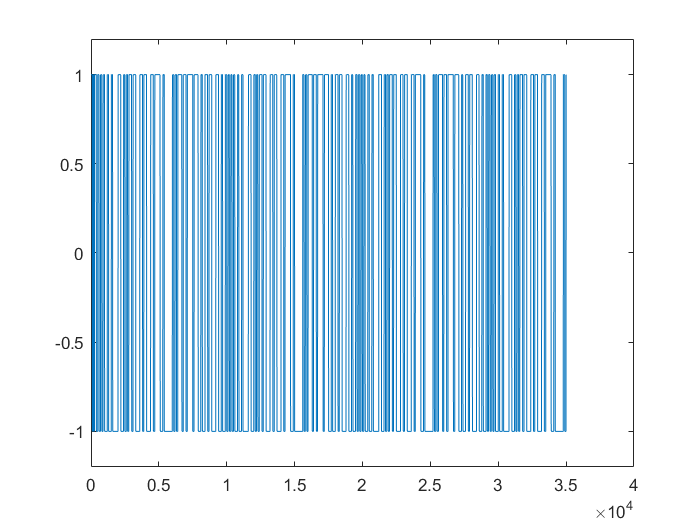

%% 位同步
data= (yout).*2-1;
L=length(data);
C=zeros(L+1,1);
datanew=zeros(L+1,1);
for i=2:L
    if(data(i)~=data(i-1))
        a=0.75;
    else
        a=1;
    end
    C(i)=a*C(i-1)+(2^32)/96; 
    if(C(i)>2^32)
        datanew(i)=data(i);
        C(i)=C(i)-2^32;
    end
end
plot((yout).*2-1)
ylim([-1.2, 1.2]);
hold on

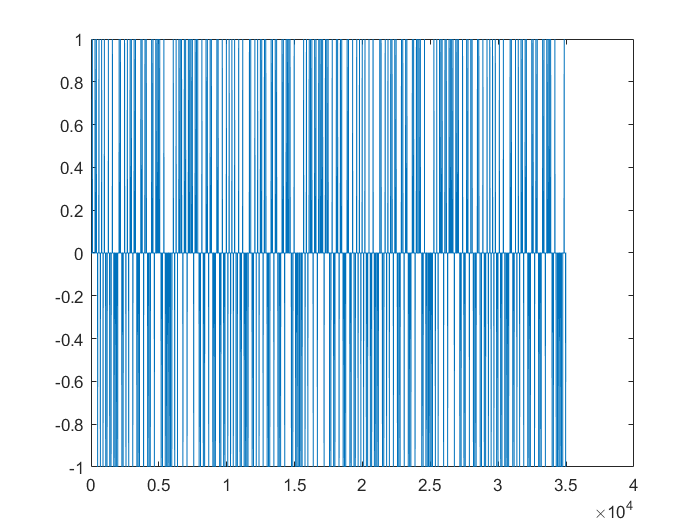

figure
plot(datanew)

datanew(datanew==0)=[];
datareal=(datanew+1)/2;
%% 帧同步
xorarrary=[1 0 1 0 1 0 1 0]';
judge=ones(1,8);
n=zeros(length(datareal),1);
for i=1:(length(datareal)-7)
    judge=xor(datareal(i:i+7),xorarrary);
    if(any(judge)==0)
        n(i+8)=i+8;
    end
end
%% 字符恢复
framehead=n(n~=0);
for i=1:length(framehead)
    if(i~=length(framehead))
        decode=char(zeros(1,floor((framehead(i+1)-8-framehead(i))/8)));
    else
        decode=char(zeros(1,floor((1+length(datareal)-framehead(i))/8)));
    end
    m=1;
    if(i~=length(framehead))
        for q=framehead(i):8:(framehead(i+1)-16)
            decodebefore=num2str(datareal(q));
            for k=1:7
                decodebefore=strcat(decodebefore,num2str(datareal(q+k)));
            end
            decodebefore=char(bin2dec(decodebefore));
            decode(m)=decodebefore;
            m=m+1;
        end
        disp(['frame',num2str(i),':',decode])
    else
         for q=framehead(i):8:(length(datareal)-7)
            decodebefore=num2str(datareal(q));
            for k=1:7
                decodebefore=strcat(decodebefore,num2str(datareal(q+k)));
            end
            decodebefore=char(bin2dec(decodebefore));
            decode(m)=decodebefore;
            m=m+1;
         end
         disp(['frame',num2str(i),':',decode])
    end
end

frame1:Hello World
frame2:Hello World
frame3:Hello World


frame4:Hello 
